## 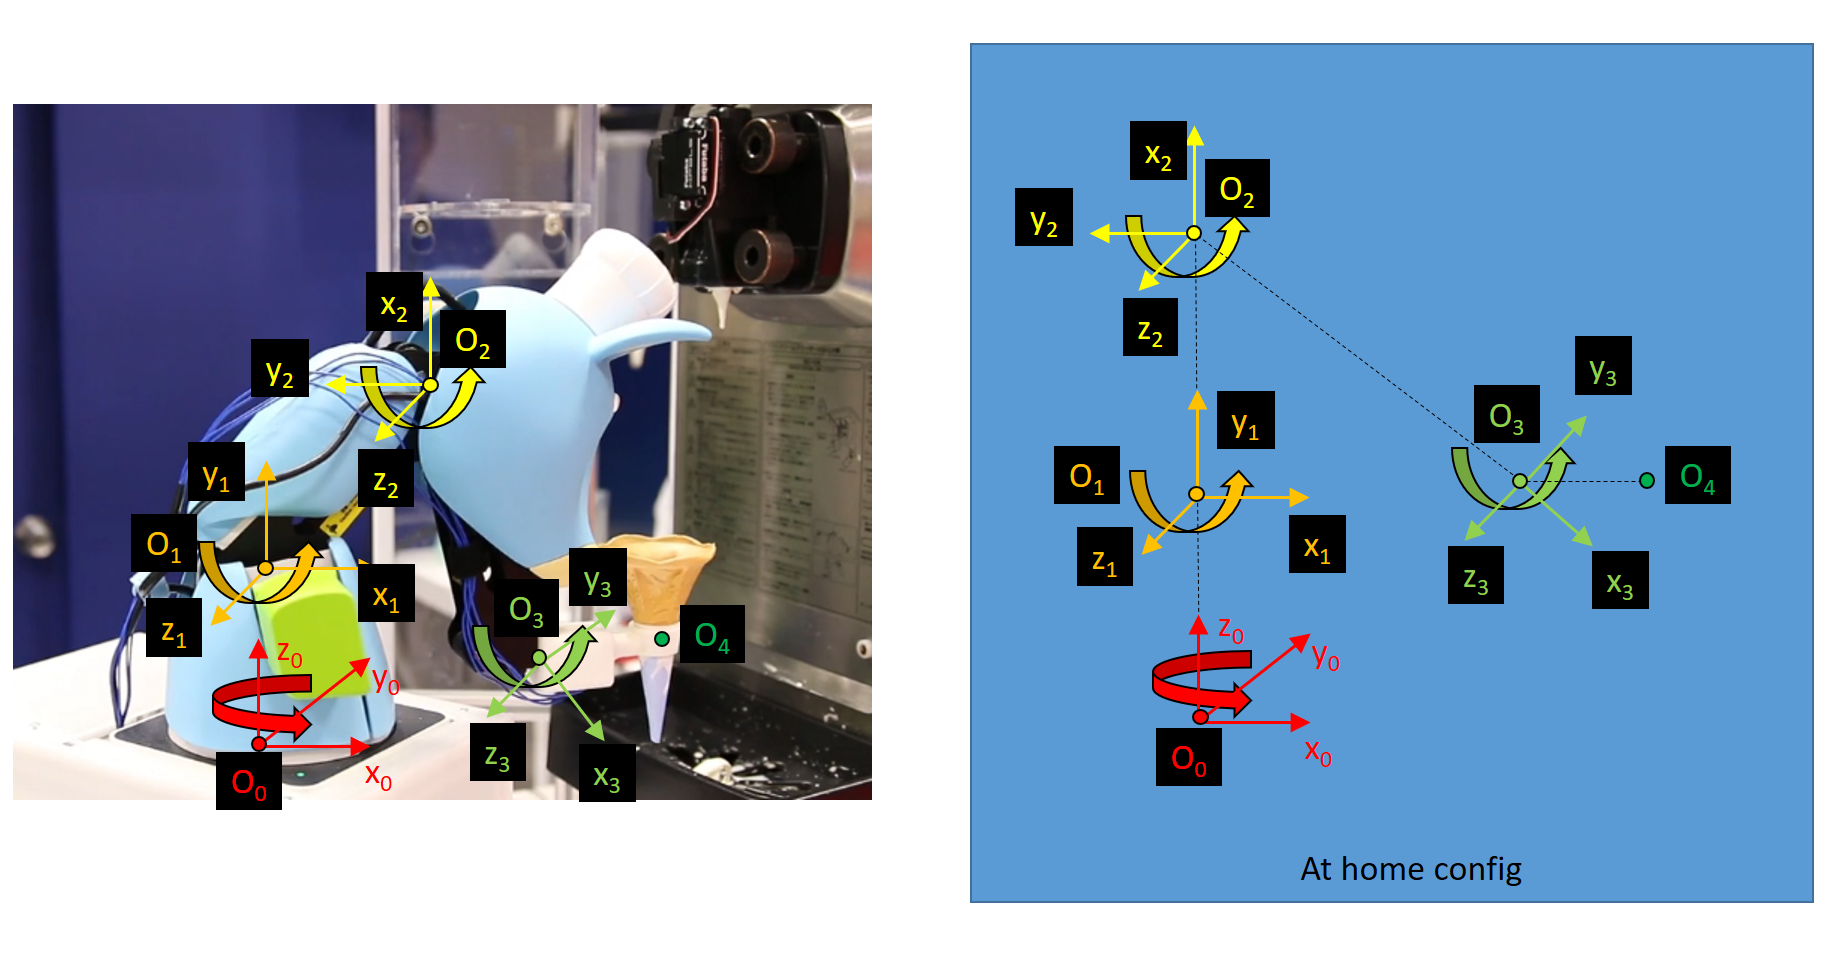

## Methods

From the DH table that we've generated for the robotic arm, we can generate the Jacobian for the arm. Once we have the Jacobian, we can determine both end effector velocities (linear and angular) as well as try to find if any singularities exist within the arm design.

The Jacobian of our arm will be a 6x4 matrix - 3 rows for each of the linear and angular velocities, and then a column for each joint on the robotic arm. Typically, the equations for the Jacobian of a given robotic joint are, for prismatic joints:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a prismatic joint*

...and for revolute joints, the Jacobian is found through:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} x\left(o_n -o_{i-1} \right)\\
z_{i-1} 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a revolute joint*

Our arm is a four axis robot with each joint being a revolute joint. As such, the equation for the Jacobian that we'll use is:


$$J=\left\lbrack \begin{array}{cccc}
z_0 x\left(o_4 -o_0 \right) & z_1 x\left(o_4 -o_1 \right) & z_2 x\left(o_4 -o_2 \right) & z_3 x\left(o_4 -o_3 \right)\\
z_0  & z_1  & z_2  & z_3 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for our robot arm*

When a Jacobian's determinant is equal to 0, the Jacobian is of a lower rank than the number of joints in the robot. As such, we have achieved a singularity. Unfortunately, the Jacobian for a 4 axis arm is not square, so we can not make use of the determinant of the Jacobian. We can, however, make use of two approaches that will allow us to utilize this methodolgy.

The first is that the first axis, $o_0$, acts as a rotation around the Z axis. No other joint moves along this axis, and thus the links of the robot arm can not form a singularitiy based on input from the first axis. Thus, we can ignore this axis when considering the Jacobian purely for singularities.

The other aspect that we can utilize is that the Jacobian can be decoupled. We will break the Jacobian into two square 3x3 matricies - the top matrix, $J_l$, consisting of the linear velocities and the bottom matrix, $J_a$consisting of the angular velocities. Therefore:


$$J=\left\lbrack \begin{array}{c}
J_l \\
J_a 
\end{array}\right\rbrack$$


$J_l$ and $J_a$ are square matricies, and thus our determinant heck can work. Here, if either $J_l$ or $J_a$ have a determinant of 0, we have reached a singularity.

We can also use **single value decomposition**, or **SVD**, to determine if the Jacobian matrix is close to losing rank. Finding the minimum in the resulting SVD of the Jacobian is also sign that the Jacobian matrix is close to uninvertible and thus a singular configuration is achieved.

Unfortunately, with our 4 axis arm configuration, with 3 serial joints with parallel z-axis, our arm is always in a singular configuration. No matter the position of the arm, we do not have enough degrees of freedom for our robot arm configuration to avoid constantly being at a singularity.

## Results

We are going to represent our Jacobian first symbollically, and then numerically to prove that we are always in a singular configuration. First, we shall find the analytical symbolic representation of our Jacobian. To see how we generate this, please refer to the *jacobian_from_dh_table* function defined below.

syms theta1 theta2 theta3 theta4 gamma d1 a2 a3 a4

dh_table = {
             [theta1                d1      0       0],
             [theta2+(pi/2)         0       a2      0],
             [theta3-(pi/2)-gamma   0       a3      0],
             [theta4                0       a4      0],
           };

j = jacobian_from_dh_table(dh_table, true)

$$j = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sigma_{1} & -\sigma_{3}-a_{3}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right) & -\sigma_{3}\\ \sigma_{2} & \sigma_{2} & \sigma_{4}+a_{3}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right) & \sigma_{4}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 1 & 1 & 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sigma_{3}-a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)-a_{3}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\sigma_{4}-a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{3}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}\right)\\ \sigma_{3}=a_{4}\,\sin\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{4}=a_{4}\,\cos\left(\theta_{1}-\gamma +\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

Here we see our resulting analytical representation of the Jacobian.


$$\begin{array}{l}
\left(\begin{array}{cccc}
\sigma_1  & \sigma_1  & -\sigma_3 -a_3 \,\mathrm{sin}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right) & -\sigma_3 \\
\sigma_2  & \sigma_2  & \sigma_4 +a_3 \,\mathrm{cos}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right) & \sigma_4 \\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & 1 & 1 & 1
\end{array}\right)\\
\mathrm{}\\
\mathrm{where}\\
\mathrm{}\\
\mathrm{\ \ }\sigma_1 =-\sigma_3 -a_2 \,\mathrm{cos}\left(\theta_1 +\theta_2 \right)-a_3 \,\mathrm{sin}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_2 =\sigma_4 -a_2 \,\mathrm{sin}\left(\theta_1 +\theta_2 \right)+a_3 \,\mathrm{cos}\left(\theta_1 -\gamma +\theta_2 +\theta_3 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_3 =a_4 \,\mathrm{sin}\left(\theta_1 -\gamma +\theta_2 +\theta_3 +\theta_4 \right)\\
\mathrm{}\\
\mathrm{\ \ }\sigma_4 =a_4 \,\mathrm{cos}\left(\theta_1 -\gamma +\theta_2 +\theta_3 +\theta_4 \right)
\end{array}$$


Earlier, we discussed how ew are always in a singular configuration. To prove this, select any combination of angles for our given joints - we shall demonstrate how, irregardless of your configuration, you will be in a singular configuration.

theta1 = 45;
theta2 = 45;
theta3 = 32;
theta4 = 81;
gamma = 90;
d1 = 1;
a2 = 1;
a3 = 1;
a4 = 1;

Given this configuration, we will find the numerical Jacobian for this configuration. First, we create a DH table with values representing the chosen configuration.

theta = thetas(step)

theta = 359

dh_table = {
             [theta1                d1      0       0],
             [theta2                0       a2      0],
             [theta3-90-gamma       0       a3      0],
             [theta4                0       a4      0],
           };

Here, we can calulate our resultant numerical Jacobian:

j = jacobian_from_dh_table(dh_table)

j =    -0.5427   -0.5427    0.4573   -0.3907
    1.4504    1.4504    1.4504    0.9205
         0         0         0         0
         0         0         0         0
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


Once we have that, we can prove either through looking at SVD or decoupling our above Jacobian via the last three links, we are always in a singular configuration.

j_svd = svd(j)

j_svd =     3.3671
    0.8373
    0.2658
         0


min(j_svd)

ans = 0


j_l = j(1:3, 2:4)

j_l =    -0.5427    0.4573   -0.3907
    1.4504    1.4504    0.9205
         0         0         0


j_a = j(4:6, 2:4)

j_a =      0     0     0
     0     0     0
     1     1     1



det(j_l)

ans = 0

det(j_a)

ans = 0

### Functions

#### z_from_transform

Given a transformation, grab the z rotation column and return it as a matrix. This is useful for the Jacobian matrix calculations.

function z = z_from_transform(transform)
    z = transform(1:3, 3);
end

#### translation_from_transform

Given a transformation, isolate the translation column from it. This is useful for the Jacobian matrix calculations.

function o = translation_from_transform(transform)
    o = transform(1:3, 4);
end

#### transformations_from_dh_table

Given a DH table, move through each row and create a series of transformations back to the base (0th frame). This function returns a singular cell of each transformation relative to its frame transformation - where the i-th cell is the $H_i^0$ transformation.

function transforms = transforms_from_dh_table(dh_table, vargin)
    transforms = {};
    transform = 1;
    for row = 1:length(dh_table)
        if nargin == 2
            transforms{end+1} = simplify(transform * transform_from_dh_row(dh_table, row, true));
        else
            transforms{end+1} = transform * transform_from_dh_row(dh_table, row);
        end
        transform = transforms{end};
    end
end

#### jacobian_from_dh

Given a DH table, generate the Jacobian for that DH table. If an additional, second argument is passed if the DH table contains symbolic values, allowing us to do symbolic Jacobian generation instead of a numeric calculation. Extra steps are handled for symbolics - sin vs sind (radians over degrees) and routinely tries to simplify the Jacobian as it is generated.

function j = jacobian_from_dh_table(dh_table, vargin)
    if nargin == 2
        % Initialize our jacobian matrix
        j = sym(zeros(6, length(dh_table)));
        transforms = transforms_from_dh_table(dh_table, true);
    else
        % Initialize our jacobian matrix
        j = zeros(6, length(dh_table));
        transforms = transforms_from_dh_table(dh_table);
    end
    
    o_n = translation_from_transform(transforms{length(dh_table)});
    
    % Prep each row
    for row = 1:length(dh_table)
        row;
        if row == 1
           z_i = [0; 0; 1;];
        else
           transform = transforms{row-1}; 
           z_i = z_from_transform(transform);
        end
        
        if row == 1
           o_i = [0; 0; 0;]; 
        else
           transform = transforms{row-1};
           o_i = translation_from_transform(transform);
        end
        o_i;
        if nargin == 2
            j(1:3, row) = simplify(cross(z_i, o_n-o_i));
        else
            j(1:3, row) = cross(z_i, o_n-o_i);
        end
        cross(z_i, o_n-o_i);
        j(4:6, row) = z_i;
    end
end

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then generates a transform for the given link.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end